# Detect Objects Using YOLOv8 Network Deployed To FPGA

This example shows how to deploy a trained You Only Look Once (YOLO) v8 object detector to a target FPGA board.

## Download the Pretrained Network

Load the network. This example uses `Yolov8n`, the nano version of the YOLOv8 pretrained model.

% Add the YOLOv8 files onto the MATLAB path
addpath(genpath("Pretrained-YOLOv8-Network-For-Object-Detection-main"));
% Load the network
modelName = 'yolov8n';
model = helper.downloadPretrainedYOLOv8(modelName);

Pretrained yolov8n network already exists.



net = model.yolov8Net

net =   dlnetwork with properties:

         Layers: [213×1 nnet.cnn.layer.Layer]
    Connections: [303×2 table]
     Learnables: [126×3 table]
          State: [0×3 table]
     InputNames: {'images'}
    OutputNames: {'x_model_22_Concat'  'x_model_22_Concat_1'  'x_model_22_Concat_2'}
    Initialized: 1

  View summary with summary.


Preprocess the network to be compatible for deployment.

net = helper.hdl.preprocessNetwork(net);

### Replacing split layer 'splitLayer1' with a dlhdl.layer.sliceLayer.
### Replacing split layer 'splitLayer2' with a dlhdl.layer.sliceLayer.
### Replacing split layer 'splitLayer3' with a dlhdl.layer.sliceLayer.
### Replacing split layer 'splitLayer4' with a dlhdl.layer.sliceLayer.
### Replacing split layer 'splitLayer5' with a dlhdl.layer.sliceLayer.
### Replacing split layer 'splitLayer6' with a dlhdl.layer.sliceLayer.
### Replacing split layer 'splitLayer7' with a dlhdl.layer.sliceLayer.
### Replacing split layer 'splitLayer8' with a dlhdl.layer.sliceLayer.
### Replacing sigmoid and multiplication layers 'x_model_0_act_Sigm_1' and 'x_model_0_act_Mul' with a swishLayer having the name 'x_model_0_act_Mul'.
### Replacing sigmoid and multiplication layers 'x_model_1_act_Sigm_1' and 'x_model_1_act_Mul' with a swishLayer having the name 'x_model_1_act_Mul'.
### Replacing sigmoid and multiplication layers 'x_model_2_cv1_act__2' and 'x_model_2_cv1_act__1' with a swishLayer having the name 

Load the data set and perform a test detection on an image randomly chosen from the data set.

% Read test image.
img = imread(fullfile('data','inputTeam.jpg'));

% Get number of output classes of the network
classNames = helper.getCOCOClassNames;
numClasses = size(classNames,1);
% Perform detection
executionEnvironment = 'auto';
[bboxes,scores,labelIds] = detectYOLOv8(net, img, numClasses, executionEnvironment);

% Map labelIds back to labels.
labels = classNames(labelIds);

% Visualize detection results.
annotations = string(labels) + ': ' + string(scores);
Iout = insertObjectAnnotation(img, 'rectangle', bboxes, annotations);
figure, imshow(Iout)

## Configure Deep Learning Processor and Generate a Bitstream

The network includes several swish layers. To deploy the network to the FPGA hardware, you must turn on the `SwishLayer` property of the `custom` module in the deep learning processor configuration. 

You can create a `dlhdl.ProcessorConfig` object from an existing bitstream and then modify the processor configuration properties to generate a custom bitstream. In this example, the target FPGA board is the Xilinx Zynq® UltraScale+™ MPSoC ZCU102 board and the date type is int8. `hPC` stores the deep learning processor configuration object created from the `zcu102_int8` bitstream. Enable the `SwishLayer` property of the `custom` module, and turn off the `SegmentationBlockGeneration` property to save FPGA resources.  

To learn how to use the generated bitstream file, see [Generate Custom Bitstream](docid:dlhdl_ug#mw_271be8bd-b787-43d3-a753-bc943d255d48).

## Deploy Quantized Network to FPGA

Preprocess the input data set to prepare the images for `int8` data type quantization.

imPre = preprocessYOLOv8Input(net, img);
imageData = augmentedImageDatastore([640,640],img);

Quantize the network by using the `dlquantizer` object. Use the `calibrate` method to exercise the network by using sample inputs to collect the range information.

dlQuantObj = dlquantizer(net,'ExecutionEnvironment','FPGA');
dlQuantObj.calibrate(imageData);

Define the target FPGA board programming interface by using the `dlhdl.Target` object. Specify that the interface is for a Xilinx board with an Ethernet interface.

hTarget = dlhdl.Target('Xilinx', 'Interface', 'Ethernet');

Prepare the network for deployment by creating a `dlhdl.Workflow` object. Specify the quantized network and the bitstream name. In this example, the target FPGA board is the Xilinx Zynq® UltraScale+™ MPSoC ZCU102 board. The bitstream uses the `int8` data type. Use the bitstream generated earlier.

bitstreamPath = fullfile('dlhdl_prj','dlprocessor.bit')

bitstreamPath = 'dlhdl_prj\dlprocessor.bit'

hW = dlhdl.Workflow("Network", dlQuantObj, "Bitstream",bitstreamPath, "Target", hTarget);

To compile the network and generate the instructions, weights, and biases for deployment, run the `compile` method of the `dlhdl.Workflow` object.

dn = compile(hW)

### Compiling network for Deep Learning FPGA prototyping ...
### Targeting FPGA bitstream C:\Users\vikramv\OneDrive - MathWorks\Documents\MATLAB\ExampleManager\vikramv.Bdoc.j2786291.yoloo\dlhdl-ex48666157\dlhdl_prj\dlprocessor.bit.
### The network includes the following layers:
     1   'images'                 Image Input              640×640×3 images                                                       (SW Layer)
     2   'x_model_0_conv_Conv'    2-D Convolution          16 3×3×3 convolutions with stride [2  2] and padding [1  1  1  1]      (HW Layer)
     3   'x_model_0_act_Mul'      Swish                    Swish                                                                  (HW Layer)
     4   'x_model_1_conv_Conv'    2-D Convolution          32 3×3×16 convolutions with stride [2  2] and padding [1  1  1  1]     (HW Layer)
     5   'x_model_1_act_Mul'      Swish                    Swish                                                                  (HW Layer)
     6   'x_mode

dn = struct with fields:
             weights: [1×1 struct]
        instructions: [1×1 struct]
           registers: [1×1 struct]
    syncInstructions: [1×1 struct]
        constantData: {}
             ddrInfo: [1×1 struct]
       resourceTable: [6×2 table]


To deploy the network on the Xilinx ZCU102 SoC hardware, run the `deploy` method of the `dlhdl.Workflow` object. This function uses the output of the `compile` function to program the FPGA board and download the network weights and biases. The `deploy` function starts programming the FPGA device and displays progress messages, and the required time to deploy the network.

hW.deploy

### FPGA bitstream programming has been skipped as the same bitstream is already loaded on the target FPGA.
### Loading weights to Conv Processor.
### Conv Weights loaded. Current time is 06-Nov-2024 15:54:36


Get the activations of the network using the `predict` method of the `dlhdl.Workflow` object.

% Preprocess the input
imgPreprocessed = helper.hdl.preprocessYOLOv8Input(net, img);
imgPreprocessed = dlarray(imgPreprocessed, 'SSCB');
% Run the prediction
% hwprediction = cell(size(net.OutputNames'));
hwprediction = cell(length(net.OutputNames), 1);
[hwprediction{:}] = hW.predict(imgPreprocessed, 'Profile', 'on');

### Finished writing input activations.
### Running single input activation.


              Deep Learning Processor Profiler Performance Results

                   LastFrameLatency(cycles)   LastFrameLatency(seconds)       FramesNum      Total Latency     Frames/s
                         -------------             -------------              ---------        ---------       ---------
Network                   34269889                  0.13708                       1           33075098              7.6
    x_model_0_conv_Conv     972471                  0.00389 
    x_model_0_act_Mul       489123                  0.00196 
    x_model_1_conv_Conv     597458                  0.00239 
    x_model_1_act_Mul       244518                  0.00098 
    x_model_2_cv1_conv_1    702768                  0.00281 
    x_model_2_cv1_act__1    244443

Process the FPGA output using the `postprocessYOLOv8Output` function.

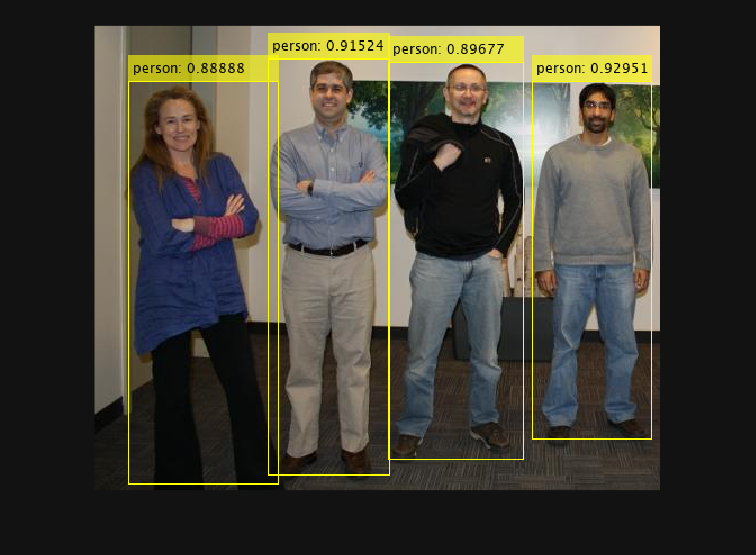

[bboxes,scores,labels] = postprocessYOLOv8Output(hwprediction, img, imgPreprocessed, numClasses);

% Visualize detection results.
annotations = string(labels) + ': ' + string(scores);
Iout = insertObjectAnnotation(img, 'rectangle', bboxes, annotations);
figure, imshow(Iout);

*Copyright 2025 The MathWorks, Inc.*